A = [10 -1 -2; -1 10 -2; -1 -1 5];
b = [72 83 42];

[x_jacobi, res_jacobi] = jacobi(A, b, 1e-6)

----------Start iteration----------
Iteration = 0 
Residual = 1 
x = 7.200000e+00 
x = 8.300000e+00 
x = 8.400000e+00 
----------End iteration----------
Iteration = 14 
Residual = 4.825162e-07 
x = 1.100000e+01 
x = 1.200000e+01 
x = 1.300000e+01 


x_jacobi =    11.0000   12.0000   13.0000


res_jacobi =     1.0000    0.2510    0.0784    0.0257    0.0086    0.0029    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


[x_gauss, res_gauss] = gauss_seidel(A, b, 1e-6)

----------Start iteration----------
Iteration = 0 
Residual = 1 
x = 7.200000e+00 
x = 9.020000e+00 
x = 1.164400e+01 
----------End iteration----------
Iteration = 8 
Residual = 8.155094e-07 
x = 1.099998e+01 
x = 1.199999e+01 
x = 1.299999e+01 


x_gauss =    11.0000   12.0000   13.0000


res_gauss =     1.0000    0.2021    0.0263    0.0032    0.0004    0.0001    0.0000    0.0000


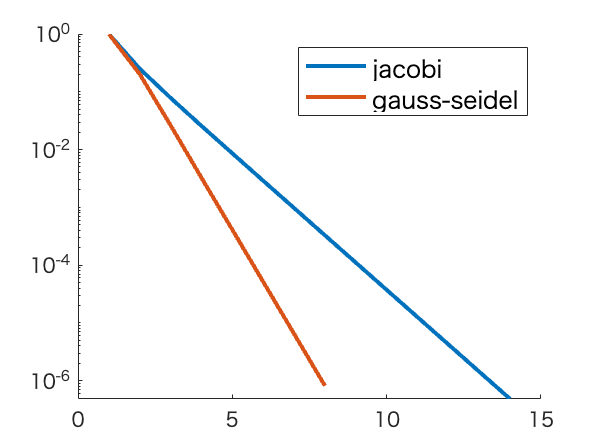

x1 = 1:length(res_jacobi);
x2 = 1:length(res_gauss);

set(gca, 'YScale', 'log')

hold on

plot(x1, res_jacobi, 'LineWidth', 2, 'DisplayName', 'jacobi');
plot(x2, res_gauss, 'LineWidth', 2, 'DisplayName', 'gauss-seidel');

hold off

lgd = legend;
lgd.FontSize = 12;